# 测试(柱坐标系)

clc
clear
close all
addpath("src\");

## 地火转移

### 参数

tof   = 506;           % days
g0    = 9.80665 ;      % m/s^2
Isp   = 3000;          % s
Tmax  = 0.4;           % N, kg*m/s^2
m0    = 1000;          % kg
a_m   = 1.54067001;    % AU
e_m   = 0.088373;
i_m   = 1.842622;      % deg
mu    = 132712440018;  % km^3/s^2
AU    = 149597870.700; % km
a_e   = 1;             % AU
e_e   = 0.0167;
tspan = 1e-1;          % day

更改参数

% Venus
% tof = 800;
% a_m = 0.72330595;
% e_m = 0.006726;

#### 归一化

DU = AU;     % km
TU = 58.135; % d
MU = m0;     %kg
ap.tf = tof / TU;
ap.mu = mu / DU^3 * TU^2 * 86400^2;
ap.g0 = g0 * 1e-3 / DU;
ap.Isp = Isp / TU / 86400;
ap.Tmax = Tmax / MU * 1e-3 / DU * TU^2 * 86400^2;
ap.m0 = m0 / MU;
ap.tspan = tspan / TU;
t = 0 : ap.tspan : ap.tf;

### 初始轨道

r_e = [a_e * (1 + e_e), 0, 0.01]';
v_e = [0, sqrt(ap.mu * (2 / norm(r_e) - 1 / a_e)), 0.01 * sqrt(ap.mu / 1)]';
[x_e, dx_e] = Cart2Cylin2(r_e, v_e);
r_m = [a_m * (1 + e_m), 0, 0.01]';
v_m = [0, sqrt(ap.mu * (2 / norm(r_m) - 1 / a_m)), 0.01 * sqrt(ap.mu / 1)]';
[x_m, dx_m] = Cart2Cylin2(r_m, v_m);
[~, x_e] = ode45(@(t, x) CylinEq(t, x, 0, ap), t, [x_e; dx_e]);
[~, x_m] = ode45(@(t, x) CylinEq(t, x, 0, ap), t, [x_m; dx_m]);
x0 = x_e(1, :)';
xf = x_m(floor(length(t) / 3), :)';

### 时间最优

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    6.963103e+00    3.135e+00    9.007e-01
    1      20    6.046010e+00    8.907e-01    7.497e-01    2.307e+00
    2      28    4.360410e+00    2.459e-01    8.470e-03    1.350e+01
    3      36    4.351982e+00    2.450e-01    4.235e-05    3.795e+02
    4      44    4.351940e+00    2.450e-01    2.118e-07    2.046e+03
    5      52    4.352929e+00    2.449e-01    9.895e-04    1.068e+04
    6      60    4.351944e+00    2.449e-01    4.947e-06    5.366e+03
    7      69    4.352945e+00    2.449e-01    1.006e-03    8.437e+03
    8      77    4.352621e+00    2.449e-01    6.820e-04    6.893e+03
    9      86    4.352621e+00    2.449e-01    6.820e-04    8.129e+03
   10      94    4.352927e+00    2.449e-01    9.878e-04    7.508e+03
   11     102    4.352938e+00    2.449e-01    9.982e-04    3.773e+03
   12     110    4.352938e+00    2.449e-01    9

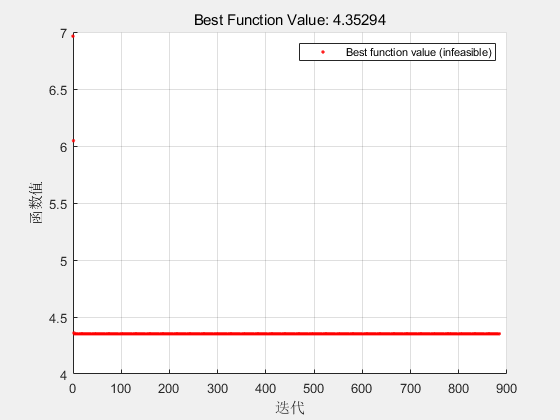


fmincon stopped by the output or plot function.



[s, lambda] = IndirOptTime(@CylinTimeEq, x0, xf, ap.tf, ap);

t = s(:, 1);
tf = t(end)

tf = 4.3519

s(:, 1) = [];
lambda

lambda = 1.0e+03 *

    7.7140
    8.2701
    8.8615
    9.8942
    8.9366
    8.6706


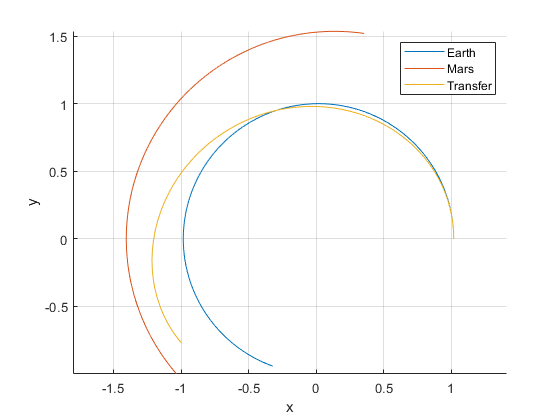

[~, x_e] = ode45(@(t, x) CylinTimeEq(t, x, ap), 0 : ap.tspan : tf, x0);
[~, x_m] = ode45(@(t, x) CylinTimeEq(t, x, ap), 0 : ap.tspan : tf, xf);
figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(s(:, 1) .* cos(s(:, 2)), s(:, 1) .* sin(s(:, 2)))
legend('Earth', 'Mars', 'Transfer')
xlabel('x')
ylabel('y')
grid on
axis equal

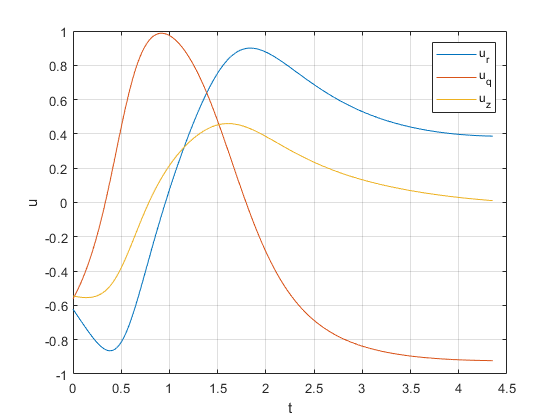

figure
plot(t, s(:, 13 : 15))
legend('u_r', 'u_q', 'u_z')
xlabel('t')
ylabel('u')
grid on

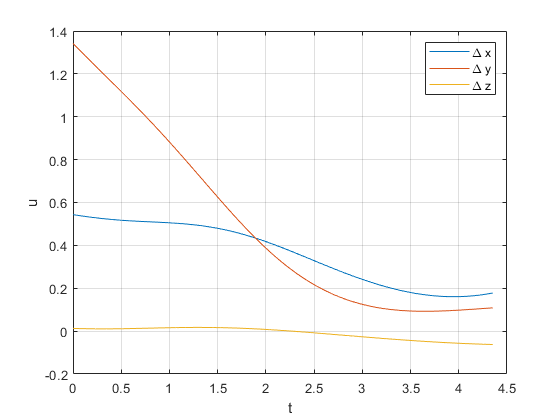

len = size(s, 1);
dd = x_m(1 : len, 1 : 3) - s(:, 1 : 3);
figure
plot(t, dd)
legend('\Delta x', '\Delta y', '\Delta z')
xlabel('t')
ylabel('u')
grid on